%% Dual-Axis Solar Tracker (Motor Model + Discrete Plant + Run + Plots)
% Author: <your name>
% Notes:
% - Plant states: x = [theta; omega; i]
% - Input: armature voltage (V)
% - Output: theta (position)

clear; close all; clc;

%% 1) Parameters (grouped)
motor.R  = 18.2214;        % Ohm
motor.L  = 0.000866;       % H
motor.Kb = 0.030941093;    % V/(rad/s)
motor.Km = 0.030941093;    % N.m/A
motor.J  = 0.00009;        % kg.m^2
motor.B  = 0.000025;       % N.m.s/rad

Ts = 0.1;                  % Discrete sample time (s)

%% 2) Build state-space model
% x1 = theta, x2 = omega, x3 = current i
A = [ 0             1               0
      0   -(motor.B/motor.J)   (motor.Km/motor.J)
      0   -(motor.Kb/motor.L)  -(motor.R/motor.L) ];

B = [0; 0; 1/motor.L];
C = [1 0 0];               % output = position
D = 0;

G  = ss(A,B,C,D);          % continuous plant
Gd = c2d(G, Ts, 'zoh');    % discrete plant

disp('✅ Continuous plant (G) and discrete plant (Gd) created.');

✅ Continuous plant (G) and discrete plant (Gd) created.



% Save in a clean way
save('d_sys.mat','G','Gd','Ts','motor');

%% 3) Run Simulink model
% Make sure Dual_Axis_Solar_Tracker.slx is in the same folder
out = sim('Dual_Axis_Solar_Tracker');

   Assuming no disturbance added to measured output #1.


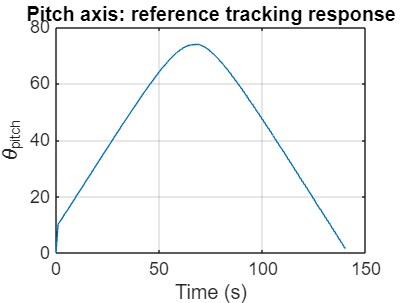


%% 4) Plotting (robust extraction)
% Recommended: use To Workspace blocks named "model1" and "model2"
% If you exported time to workspace, it will be "t". If not, take from out.

% Time
if evalin('base',"exist('t','var')")==1
    t = evalin('base','t');
elseif isprop(out,'tout')
    t = out.tout;
else
    error('Time vector not found. Add a Clock->To Workspace named t OR enable tout.');
end
t = t(:);

% Signals
if evalin('base',"exist('model1','var')")==1
    pitch = evalin('base','model1');
else
    error('model1 not found. Add a To Workspace block named model1 for pitch output.');
end

if evalin('base',"exist('model2','var')")==1
    yaw = evalin('base','model2');
else
    error('model2 not found. Add a To Workspace block named model2 for yaw output.');
end

figure; plot(t, pitch); grid on;
title('Pitch axis: reference tracking response');
xlabel('Time (s)'); ylabel('\theta_{pitch}');

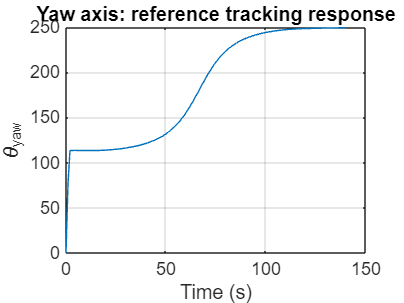


figure; plot(t, yaw); grid on;
title('Yaw axis: reference tracking response');
xlabel('Time (s)'); ylabel('\theta_{yaw}');